N = 7;

x = [1, 2, 3, 4];
y = [5, 6, 7, 8];
x1 = [1, 2, 3, 4, 0, 0, 0];
y1 = [5, 6, 7, 8, 0, 0, 0];
dftX = zeros(1,N);
dftY = zeros(1,N);
for k = 0:N-1
    for n = 0:N-1
        dftX(k+1) = dftX(k+1)+ (x1(n+1) * exp(-1j*2*pi*(n)*(k)/N)); 
        dftY(k+1) = dftY(k+1)+ (y1(n+1) * exp(-1j*2*pi*(n)*(k)/N)); 
    end
end
dftX

dftX =   10.0000 + 0.0000i  -2.0245 - 6.2240i   0.3460 + 2.4791i   0.1784 - 2.4220i   0.1784 + 2.4220i   0.3460 - 2.4791i  -2.0245 + 6.2240i


dftY

dftY =   26.0000 + 0.0000i  -0.0245 -14.9866i   2.3460 + 3.4423i   2.1784 - 4.9299i   2.1784 + 4.9299i   2.3460 - 3.4423i  -0.0245 +14.9866i


subplot(5,1,1)
stem(abs(dftX))
title('DFT of first input')

subplot(5,1,2)
stem(abs(dftY))
title('DFT of second input')

convX = conv(x, y)

convX =      5    16    34    60    61    52    32


dftConv = zeros(1,N)

dftConv =      0     0     0     0     0     0     0


for k = 0:N-1
    for n = 0:N-1
        dftConv(k+1) = dftConv(k+1)+ (convX(n+1) * exp(-1j*2*pi*(n)*(k)/N)); 
        
    end
end
dftConv

dftConv = 1.0e+02 *

   2.6000 + 0.0000i  -0.9323 + 0.3049i  -0.0772 + 0.0701i  -0.1155 - 0.0616i  -0.1155 + 0.0616i  -0.0772 - 0.0701i  -0.9323 - 0.3049i


subplot(5,1,3)
stem(convX)
title('Convolution of inputs')

y = dftX.*dftY

y = 1.0e+02 *

   2.6000 + 0.0000i  -0.9323 + 0.3049i  -0.0772 + 0.0701i  -0.1155 - 0.0616i  -0.1155 + 0.0616i  -0.0772 - 0.0701i  -0.9323 - 0.3049i


y

y = 1.0e+02 *

   2.6000 + 0.0000i  -0.9323 + 0.3049i  -0.0772 + 0.0701i  -0.1155 - 0.0616i  -0.1155 + 0.0616i  -0.0772 - 0.0701i  -0.9323 - 0.3049i


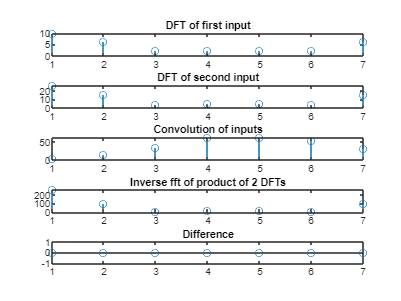

subplot(5,1,4)
stem(abs(y))
title('Inverse fft of product of 2 DFTs')

d = abs(y-dftConv);
subplot(5,1,5)
stem(round(d))
title('Difference')